# Systems Lab: Systems of ODEs in MATLAB

In this lab, you will write your own ODE system solver for the Heun method (aka the Improved Euler method), and compare its results to those of `ode45`.

You will also learn how to save images in MATLAB.

Opening the m-file lab4.m in the MATLAB editor, step through each part using cell mode to see the results. Compare the output with the PDF, which was generated from this m-file.

There are four (4) exercises in this lab that are to be handed in on the due date of the lab. Write your solutions in a separate file, including appropriate descriptions in each step. Save the m-files and the pdf-file for Exercise 4 and submit them on Quercus.

## Student Information

## Exercise 1

Objective: Write your own ODE system solver using the Heun/Improved Euler Method and compare it to `ode45`.

Details: Consider the system of 2 ODEs:

`x1'=f(t,x1,x2), x2'=g(t,x1,x2)`

This m-file should be a function which accepts as variables (t0,tN,x0,h), where t0 and tN are the start and end points of the interval on which to solve the ODE, h is the stepsize, and x0 is a vector for the initial condition of the system of ODEs `x(t0)=x0`. Name the function solvesystem_<UTORid>.m (Substitute your UTORid for [UTORid](http://utorid)). You may also want to pass the functions into the ODE the way `ode45` does (check MATLAB labs 2 and 3).

Your m-file should return a row vector of times and a matrix of approximate solution values (the first row has the approximation for `x1` and the second row has the approximation for `x2`).

Note: you will need to use a loop to do this exercise. You will also need to recall the Heun/Improved Euler algorithm learned in lectures. 

%function [time, x] = solvesystem_shinja19(f, g, t0,tN,x0,h)
 %len = round((tN-t0)/h,0);
 %time = linspace(t0, tN, len);
 %x = zeros(2, len);
 % initial Vlues:
 %time(1) = t0;
 %x(:,1) = x0; % at(:,1) % gives the first column (and so on) which will be x0
    %for i = 2:len
       % time(i) = time(i-1) + (i-1)*h;
        % First
       % x(1,i) = x(1, i-1) + h*f(time(i-1), x(1,i-1), x(2,i-1));
       % x(2,i) = x(2,i-1) + h*g(time(i-1), x(1,i-1), x(2,i-1));
        % slope of left
       % S_L = [f(time(i-1), x(1,i-1), x(2,i-1));
         %       g(time(i-1), x(1,i-1),x(2,i-1))];
        % right one
       % S_R = [f(time(i), x(1,i), x(2,i));
         %       g(time(i),x(1,i),x(2,i))];
        %improv_slope = (S_L + S_R) ./ 2;
        %x(:,i) = x(:, i -1) + h*improv_slope;
        
   % end 
% end

## Exercise 2

Objective: Compare Heun with an exact solution

Details: Consider the system of ODEs

`x1' = x1/2 - 2*x2, x2' = 5*x1 - x2`

with initial condition `x(0)=(1,1)`.

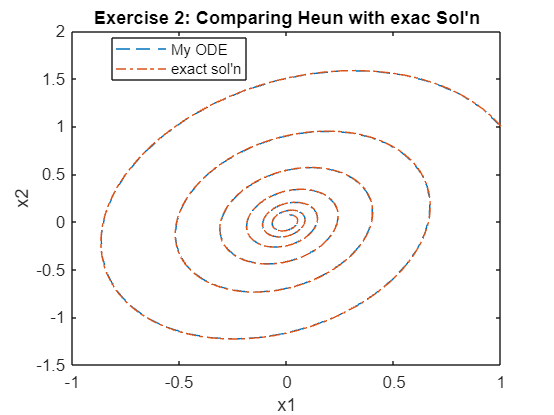

% functions
f = @(t, x1,x2) x1/2 - 2*x2;
g = @(t, x1,x2) 5*x1 - x2;
% The initial conditions
t0 = 0;
tN = 4*pi;
x0 = [1,1];
h = 0.05;
% my ODE solver (Improved Euler / solvesystem..)
[time, x] = solvesystem_shinja19(f, g, t0,tN,x0,h);
t = linspace(t0,tN,500);

x1_exact = exp(-t/4).*((cos(sqrt(151)*t/4)) + -5/sqrt(151)*sin((sqrt(151)*t/4)));
x2_exact = exp(-t/4) .* (cos(sqrt(151)*t/4) + (sqrt(151)/8) * sin(sqrt(151)*t/4) - (15/(8*sqrt(151))) * sin(sqrt(151)*t/4));
% x_exact = exp(-t/4).* (c1 [((8cos(sqrt(151)*t/4)) ; 3cos(sqrt(151)*t/4) +
% sqrt(151)*sin((sqrt(151)*t/4)))] + c2([8cos(sqrt(151)*t/4 ; 3sin(sqrt(151)*t/4 - sqrt(151)*cos((sqrt(151)*t/4))
% sqrt(151)*sin((sqrt(151)*t/4))] 
% c1 = 1/8
% c2 = 5/(-8sqrt(151))
plot(x(1,:),x(2,:),"--", x1_exact,x2_exact,"-.");

legend('My ODE', "exact sol'n", 'Location', 'Best');
title("Exercise 2: Comparing Heun with exac Sol'n");
ylabel('x2');
xlabel('x1');

Use your method from Exercise 1 to approximate the solution from `t=0` to `t=4*pi` with step size `h=0.05`.

Compute the exact solution (by hand) and plot both phase portraits on the same figure for comparison.

Your submission should show the construction of the inline function, the use of your Heun's method to obtain the solution, a construction of the exact solution, and a plot showing both. In the comments, include the exact solution.

Label your axes and include a legend.

## Exercise 3

Objective: Compare your method with Euler's Method (from `iode`).

Details: Use `iode` to plot the solution for the same problem with the same step size as on Exercise 2.

A = [1/2 -2; 5 -1];
hi = @(t, x) A * x;
x0 = [1; 1]; 
tc = 0:0.05:4*pi; 
xc = euler(hi, x0, tc);
xc(end)

ans = 1.4534

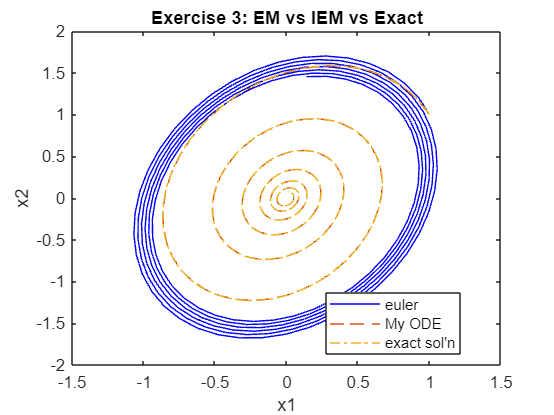

plot(xc(1,:), xc(2,:), 'b', x(1,:),x(2,:),"--", x1_exact,x2_exact,"-." );
xlabel('x1');
ylabel('x2');
legend("euler",'My ODE', "exact sol'n", 'Location', 'Best');
title("Exercise 3: EM vs IEM vs Exact");


% the approximation of EM is really bad comparing to IEM and Exact sol'n.
% The most noticiable difference is the EM is much slower than IEM. As time
% goes, this makes spiral trajectory, however, when IEM and exact solution
% reached the centre of elipse, the EM didn't even reach 1/5 of elipse.
% Therefore, we can see that rate of EM is really slower than IEM. 

Compare your solution on exercise 2, the exact solution from exercise 2 and the approximation using Euler's method. Plot the solution for Euler's method and make note of any differences.

## Saving Images in MATLAB

To do the following exercises, you will need to know how to output graphics from MATLAB. Create a folder on your Desktop (or elsewhere) to contain the files generated by these exercises. Make this folder the "Current Folder" in the left side of the main MATLAB window. This will ensure that the files output by MATLAB end up in the folder you created.

To save an image of a phase portrait, use the following steps:

1. Get the phase portrait looking the way you want in the `iode` window. 

2. Leaving `iode` open, switch to the main MATLAB window.

3. Type the command `print -dpng -r300 'filename.png'` in the command window.

This command will create a PNG graphic called `filename.png` in the current folder. The `-dpng` option tells MATLAB to output the graphic in PNG format; MATLAB also allows output in other formats, such as BMP, EPS, PNG and SVG. The `-r300` option tells MATLAB to set the resolution at 300 dots per inch and can be adjusted if you wish.

## Exercise 4

Objective: Analyze phase portraits.

Details: Compile the results of the following exercises into a single document (e.g. using a word processor) and export it to `PDF` for submission on Quercus. 

% All the questinos of (a) - (c) for 4.1 - 4.10, is included in seperated PDF file. 

For each of the first-order systems of ODEs 4.1 to 4.10 below, do the following exercises:

(a) Generate a phase portrait for the system (centre the graph on the equilibrium point at (0,0)). Include a few trajectories.

(b) Classify the equilibrium on asymptotic stability, and behaviour (sink, source, saddle-point, spiral, center, proper node, improper node) - check table 3.5.1 and figure 3.5.7. Classify also as for clockwise or counterclockwise movement, when relevant.

(c) Compute the eigenvalues of the matrix (you do not need to show your calculations). Using the eigenvalues you computed, justify part (b).

To avoid numerical error, you should use Runge-Kutta solver with a step size of `0.05`. Change the display parameters, if necessary, to best understand the phase portrait.

4.1. `dx/dt = [2 1; 1 3] x`

4.2. `dx/dt = [-2 -1; -1 -3] x`

4.3. `dx/dt = [-4 -6; 3 5] x`

4.4. `dx/dt = [4 6; -3 -5] x`

4.5. `dx/dt = [0 -1; 1 -1] x`

4.6. `dx/dt = [0 1; -1 1] x`

4.7. `dx/dt = [2 8; -1 -2] x`

4.8. `dx/dt = [-2 -8; 1 2] x`

4.9. `dx/dt = [-8 5; -13 8] x`

4.10. `dx/dt = [8 -5; 13 -8] x`